clear;
clc;

#### 一、用FFT命令，计算下列信号的频谱，利用subplot绘制各信号的时域波形、幅度谱、相位谱。

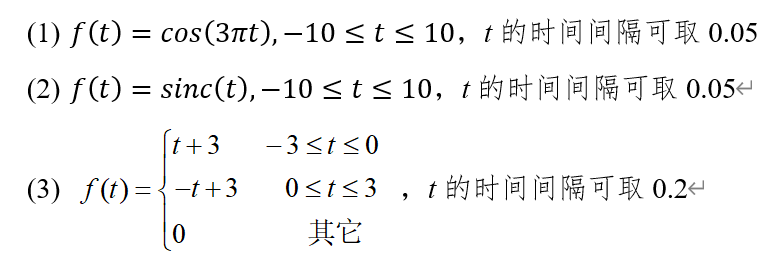

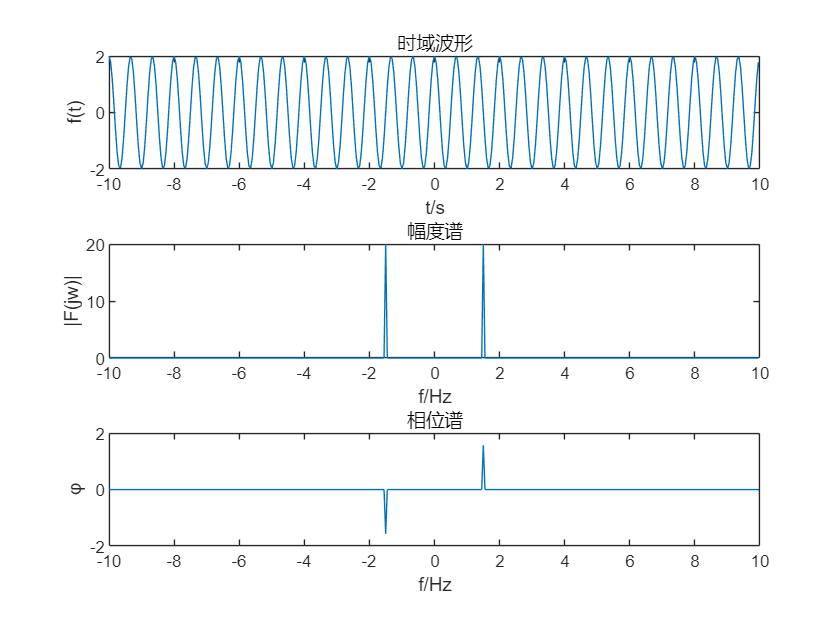

%%%%%%%%%(1)%%%%%%%%%%
%参数设置
fs=1/0.05;
N=20*fs;
t=(-N/2:N/2-1)/fs;
freq=1.5;

%时域
x=2*cos(2*pi*freq*t).*(stepfun(t,-10)-stepfun(t,10));
%画图
figure();
subplot(3,1,1);
plot(t,x);
xlabel('t/s');
ylabel('f(t)');
title('时域波形');

%频域
F=fft(x);
fshift=(0:N-1)*fs/N-fs/2;%设置频率刻度
Y=fftshift(abs(F)/fs);%计算幅度
phi=angle(F);%计算相位
Th=0.1;
phidex=find(Y<Th);
phi(phidex)=0;%消抖
%画图
subplot(3,1,2);
plot(fshift,Y);
xlabel('f/Hz');
ylabel('|F(jw)|');
title('幅度谱');
subplot(3,1,3);
plot(fshift,phi);
xlabel('f/Hz');
ylabel('φ');
title('相位谱');

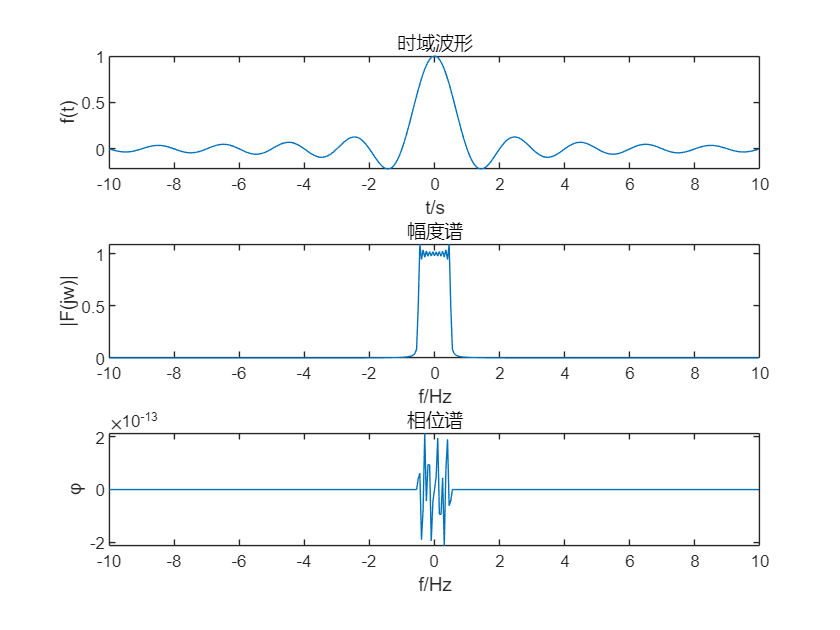


%%%%%%%%%(2)%%%%%%%%%%
%参数设置
fs=1/0.05;
N=20*fs;
t=(-N/2:N/2-1)/fs;
freq=1/2/pi;

%时域
x=sinc(t).*(stepfun(t,-10)-stepfun(t,10));
%画图
figure();
subplot(3,1,1);
plot(t,x);
xlabel('t/s');
ylabel('f(t)');
title('时域波形');

%频域
F=fft(x);
fshift=(0:N-1)*fs/N-fs/2;%设置频率刻度
Y=fftshift(abs(F)/fs);%计算幅度
phi=angle(F);%计算相位
Th=0.1;
phidex=find(Y<Th);
phi(phidex)=0;%消抖
%画图
subplot(3,1,2);
plot(fshift,Y);
xlabel('f/Hz');
ylabel('|F(jw)|');
title('幅度谱');
subplot(3,1,3);
plot(fshift,phi);
xlabel('f/Hz');
ylabel('φ');
title('相位谱');

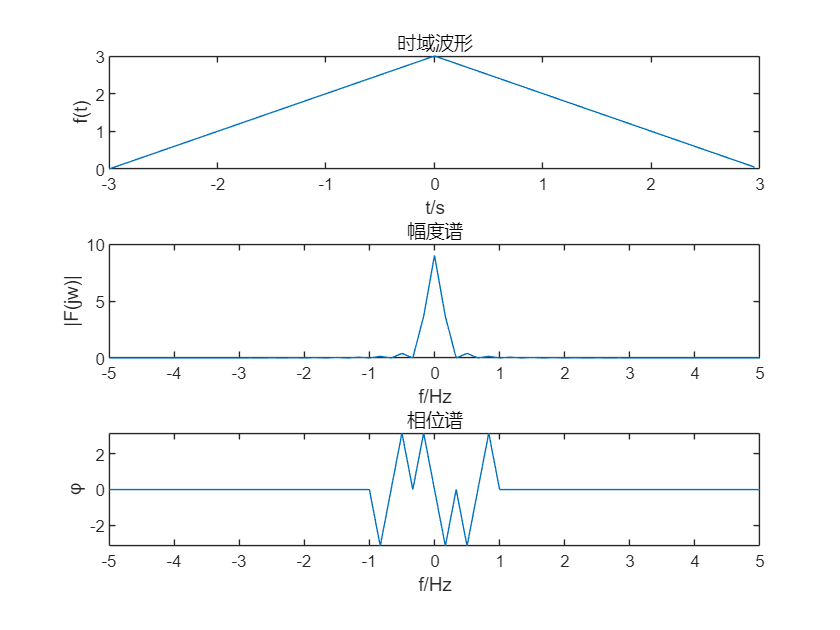



%%%%%%%%%(3)%%%%%%%%%%
%参数设置
fs=1/0.05;
N=6*fs;
t=(-N/2:N/2-1)/fs;

%时域
x=(t+3).*(stepfun(t,-3)-stepfun(t,0))+(-t+3).*(stepfun(t,0)-stepfun(t,3));
%画图
figure();
subplot(3,1,1);
plot(t,x);
xlabel('t/s');
ylabel('f(t)');
title('时域波形');

%频域
F=fft(x);
fshift=(0:N-1)*fs/N-fs/2;%设置频率刻度
Y=fftshift(abs(F)/fs);%计算幅度
phi=angle(F);%计算相位
Th=0.1;
phidex=find(Y<Th);
phi(phidex)=0;%消抖
%画图
subplot(3,1,2);
plot(fshift,Y);
xlim([-5,5]);
xlabel('f/Hz');
ylabel('|F(jw)|');
title('幅度谱');
subplot(3,1,3);
plot(fshift,phi);
xlim([-5,5]);
xlabel('f/Hz');
ylabel('φ');
title('相位谱');

clear;
clc;

#### 二、已知离散时间序列*x*(*k*)={1,2,3,4,5,6,6,5,4,3,2,1}，利用FFT命令画出该信号的幅度谱，频率间隔2*pi/100。

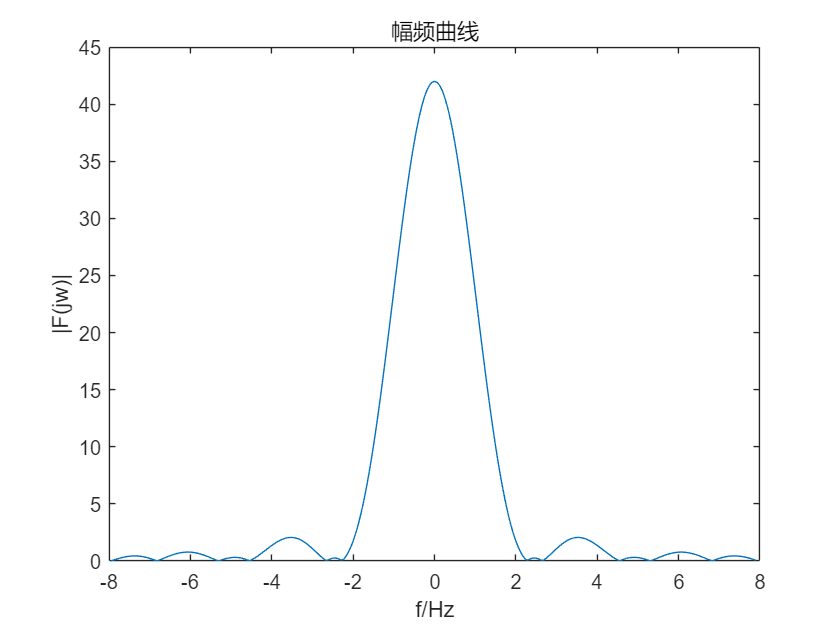

x=[1 2 3 4 5 6 6 5 4 3 2 1];
fs4=(2*pi)/100;%频率间隔
point=128;
fshift=(-point:point-1)*(1/fs4/point/2);%只显示一定范围
y41=fft(x,point*2);
y42=fftshift(y41);
figure();
plot(fshift,abs(y42));
xlabel('f/Hz');
ylabel('|F(jw)|');
title('幅频曲线');

clear;
clc;

#### `三、`已知下列*H*(*s*)或*H*(*z*)，请分别画出频率特性曲线

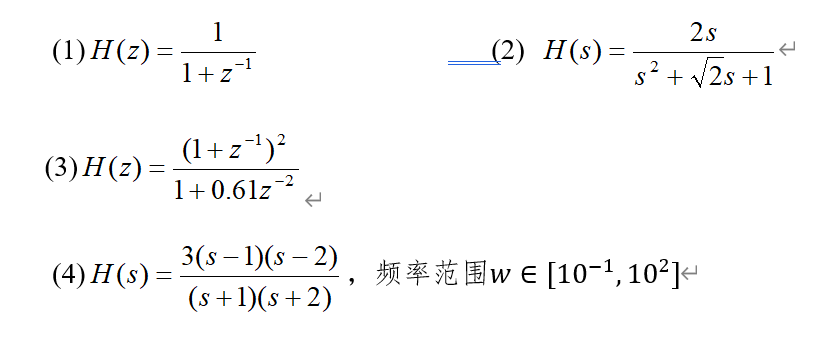

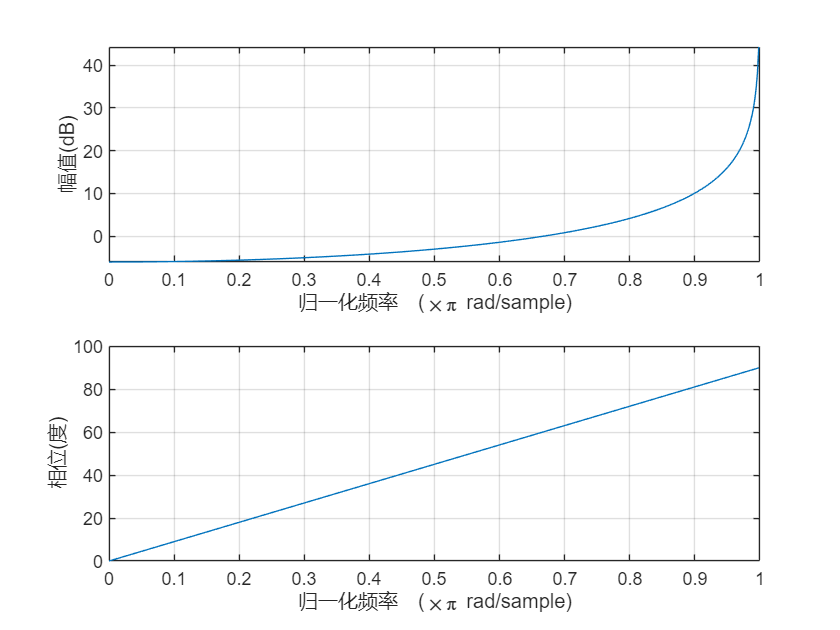

%(1)
A1=[1];
B1=[1 1];
figure(5);
freqz(A1,B1);

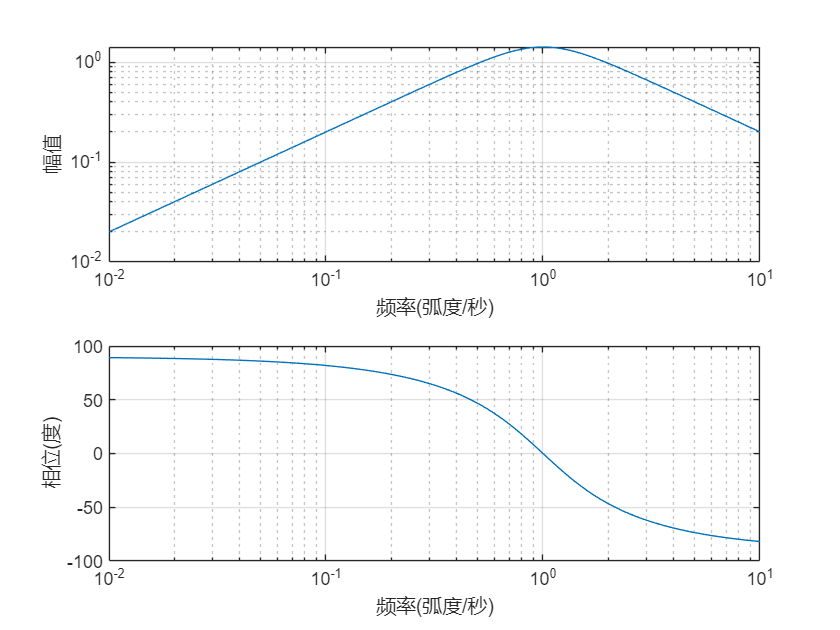

%(2)
A2=[2 0];
B2=[1 sqrt(2) 1];
figure(6);
freqs(A2,B2);

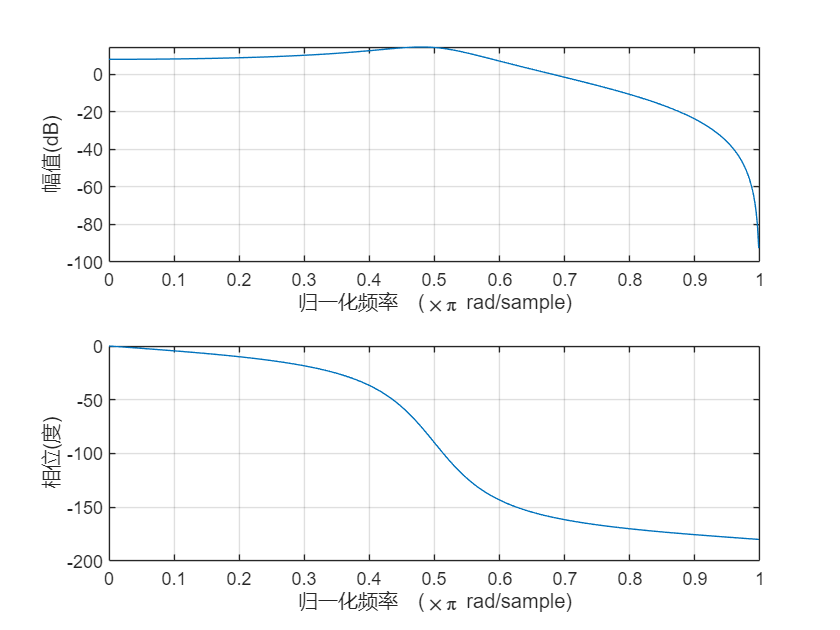

%(3)
A3=[1 2 1];
B3=[1 0 0.61];
figure(7);
freqz(A3,B3);

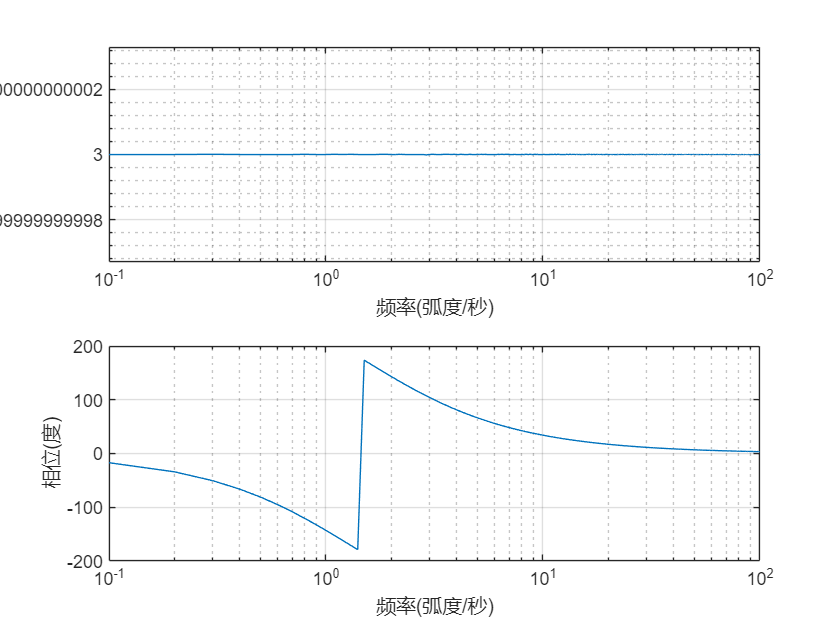

%(4)
z=[1 2].';
p=[-1 -2].';
k=[3];
[A4,B4]=zp2tf(z,p,k);
w=0.1:0.1:100;
figure(8);
freqs(A4,B4,w);

clear;
clc;

四、衰减正弦信号为

####  

（1）画出*f*=0.0625、*f*=0.4375时的时域波形；

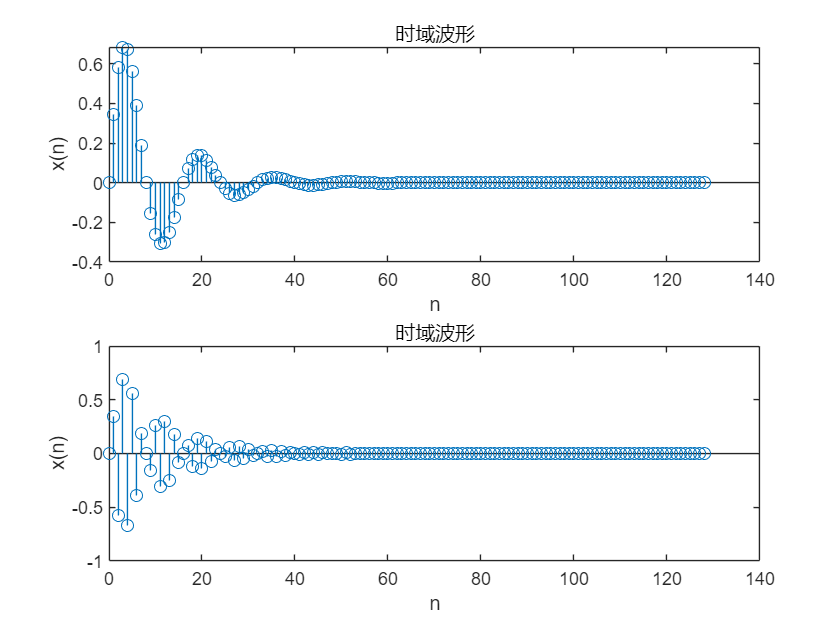

n=0:128;
%I.f=0.0625
f1=0.0625;
x1=exp(-0.1*n).*sin(2*pi*f1*n);
figure(9);
subplot(2,1,1);
stem(n,x1);
xlabel('n');
ylabel('x(n)');
title('时域波形');
%II.f=0.4375
f2=0.4375;
x2=exp(-0.1*n).*sin(2*pi*f2*n);
subplot(2,1,2);
stem(n,x2);
xlabel('n');
ylabel('x(n)');
title('时域波形');

（2）绘制出频谱，并分析两种情况下频谱图的差异和产生差异的原因

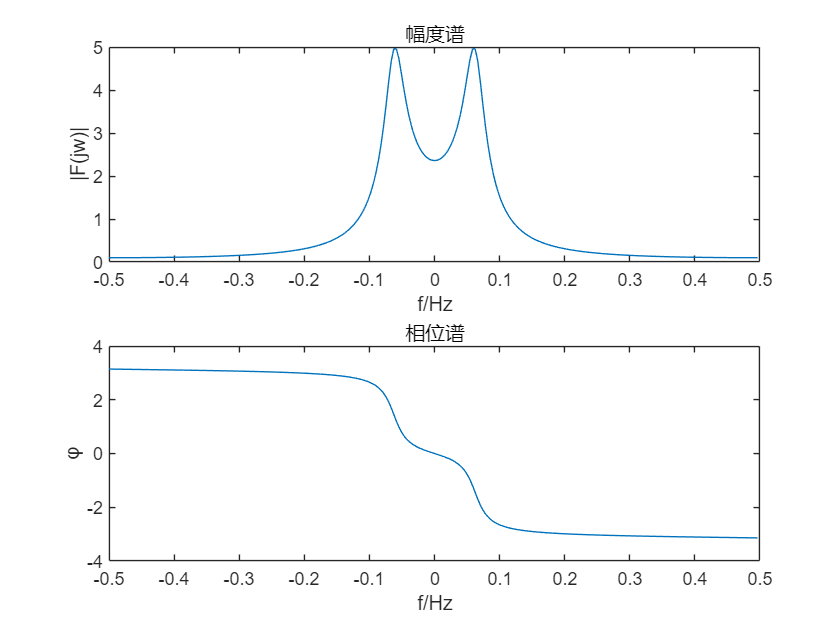

%I.f=0.0625
fs=1;
point=128;
fshift=(-point:point-1)*(fs/point/2);

y11=fft(x1,point*2);
y12=fftshift(y11);
figure(10);
subplot(2,1,1);
plot(fshift,abs(y12));
xlabel('f/Hz');
ylabel('|F(jw)|');
title('幅度谱');
subplot(2,1,2);
plot(fshift,angle(y12));
xlabel('f/Hz');
ylabel('φ');
title('相位谱');

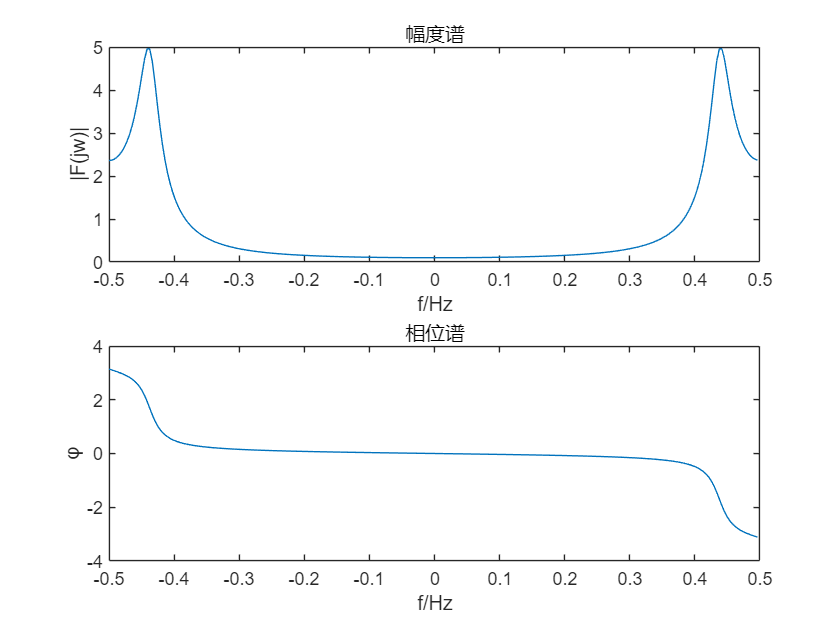

%II.f=0.4375
fs=1;
point=128;
fshift=(-point:point-1)*(fs/point/2);
y11=fft(x2,point*2);
y12=fftshift(y11);
figure(11);
subplot(2,1,1);
plot(fshift,abs(y12));
xlabel('f/Hz');
ylabel('|F(jw)|');
title('幅度谱');
subplot(2,1,2);
plot(fshift,angle(y12));
xlabel('f/Hz');
ylabel('φ');
title('相位谱');